## **0- Clear everthing**

% clear
clc
% close all

## **1-Creat Sugeno Fuzzy Model**

% fuzzyLogicDesigner()

## **Export  model to /MATLAB Drive/IS/CruiseControl with name of *****cruise.fis***** by exporting from File menue.**

## **1-a Edit Model => Use this STEP to edit the design after experimenting in the end.**

% fuzzyLogicDesigner('cruise.fis')


**save after editing by exporting.**

## **2- Load model**

cruise=update_cruise %readfis('cruise_anfis.fis');

cruise =   sugfis with properties:

                       Name: "cruise"
                  AndMethod: "prod"
                   OrMethod: "probor"
          ImplicationMethod: "prod"
          AggregationMethod: "sum"
      DefuzzificationMethod: "wtaver"
    DisableStructuralChecks: 0
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [1×9 fisrule]

	See 'getTunableSettings' method for parameter optimization.


## **3-Build the road scene**

bump_scene %flat_scene %
%% 

## **4-Start scene**

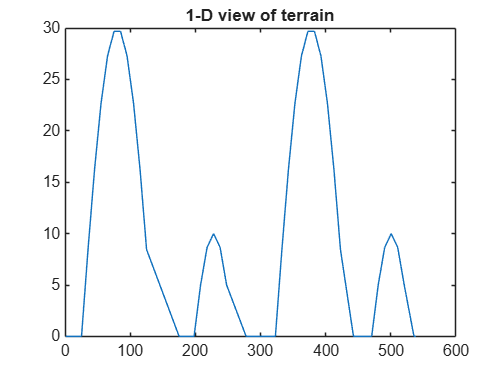

start_scene

%% 


## **5-Display**

display_scene


## **6-Run simulation**


runcar

target_speed = 15


ForceChange_list =

     []

 You can not go backwards.
It means you are getting too much negative acceleration.
you may required to put more force


## **7-Analysis - you can analyse the behaviour of your controller but hand picking the values of input.**

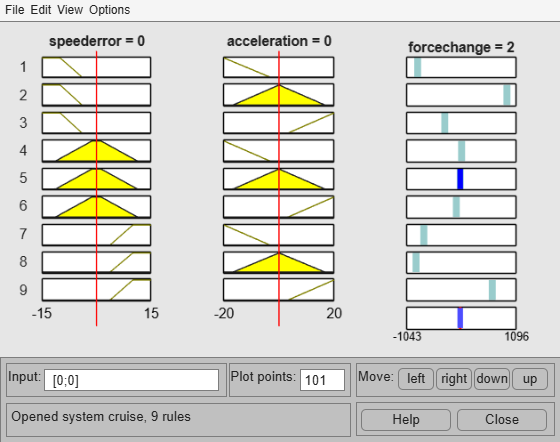

ruleview(cruise)


% or you can also give custom input to check in command line by ForceChange=evalfis(cruise,[speed_error,acceleration]);
% as  below 

% ForceChange=evalfis(cruise,[-10,-5])

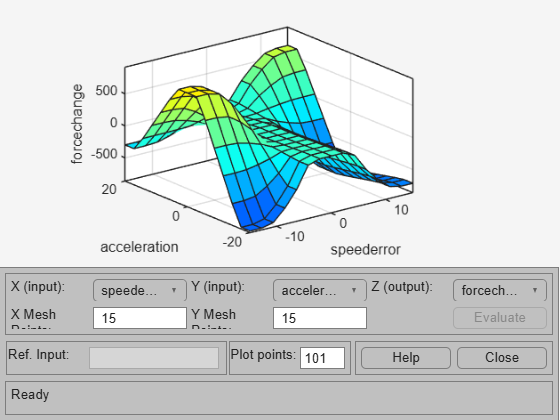

% To see the surf
surfview(cruise)